x2=x.^2

x2 =     0.0100
    0.0400
    0.0900
    0.1600
    0.2500
    0.3600
    0.4900
    0.6400
    0.8100
    1.0000



R=[ones(length(x),1), x x2]

R =     1.0000    0.0010    0.0000
    1.0000    0.0020    0.0000
    1.0000    0.0030    0.0000
    1.0000    0.0040    0.0000
    1.0000    0.0050    0.0000
    1.0000    0.0060    0.0000
    1.0000    0.0070    0.0000
    1.0000    0.0080    0.0001
    1.0000    0.0090    0.0001
    1.0000    0.0100    0.0001



B=inv((R.')*R)*((R.')*y)

B =     0.9839
   -2.9805
    0.0970



yh=R*B

yh =     0.9809
    0.9780
    0.9750
    0.9720
    0.9690
    0.9660
    0.9631
    0.9601
    0.9571
    0.9541


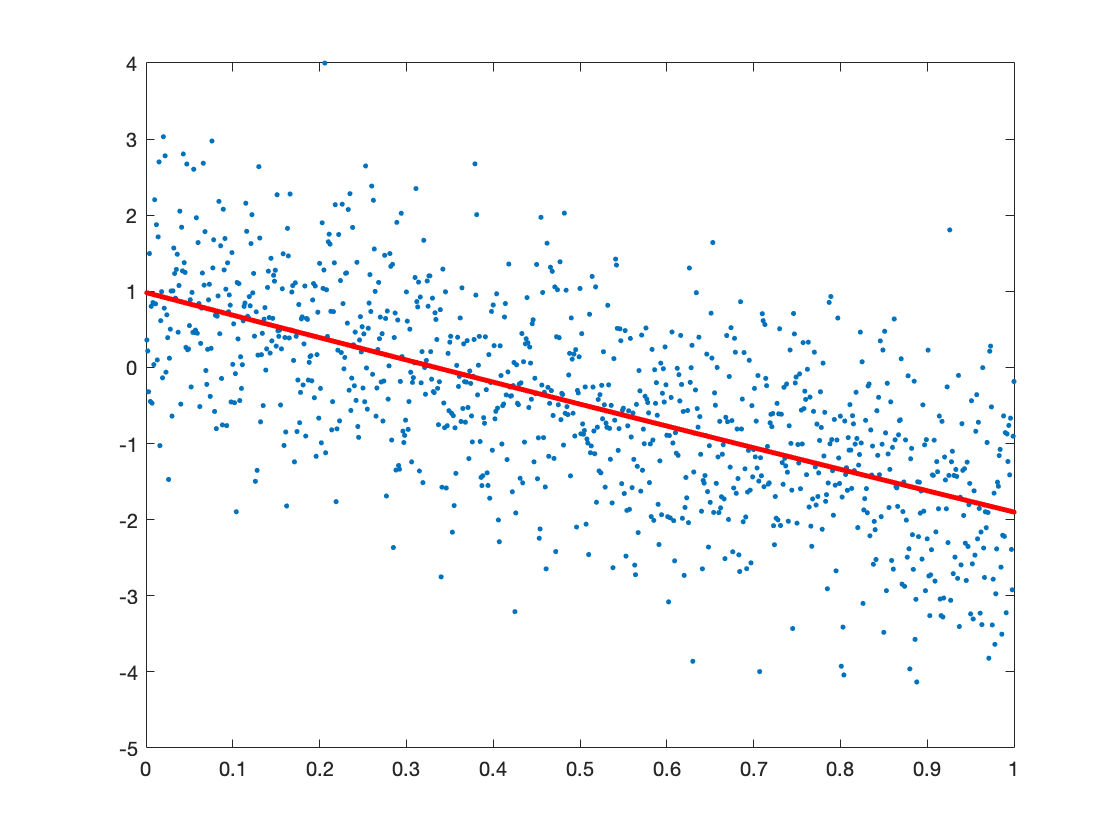


plot(x,y,'.', x,yh, '.r')


cov=inv((R.')*R)

cov =     0.0090   -0.0361    0.0301
   -0.0361    0.1924   -0.1802
    0.0301   -0.1802    0.1800



sse=(y-yh).^2

sse =     0.3836
    0.5796
    1.6754
    0.2755
    2.0049
    0.0267
    2.0522
    0.0115
    0.8461
    1.5616



sse=sum(sse)

sse = 1.0038e+03


s2ls=(2/997)*sse

s2ls = 2.0136


covd=diag(cov)

covd =     0.0090
    0.1924
    0.1800



varB=covd*s2ls

varB =     0.0182
    0.3873
    0.3625



conf_1= B + 1*sqrt(varB)

conf_1 =     1.1188
   -2.3581
    0.6990


conf_2= B - 1*sqrt(varB)

conf_2 =     0.8490
   -3.6029
   -0.5051



yh1=R*conf_1

yh1 =     1.1165
    1.1141
    1.1118
    1.1094
    1.1070
    1.1047
    1.1023
    1.1000
    1.0977
    1.0953


yh2=R*conf_2

yh2 =     0.8454
    0.8418
    0.8382
    0.8346
    0.8310
    0.8274
    0.8238
    0.8202
    0.8166
    0.8130



yh3=R*((conf_1+conf_2)/2)

yh3 =     0.9809
    0.9780
    0.9750
    0.9720
    0.9690
    0.9660
    0.9631
    0.9601
    0.9571
    0.9541


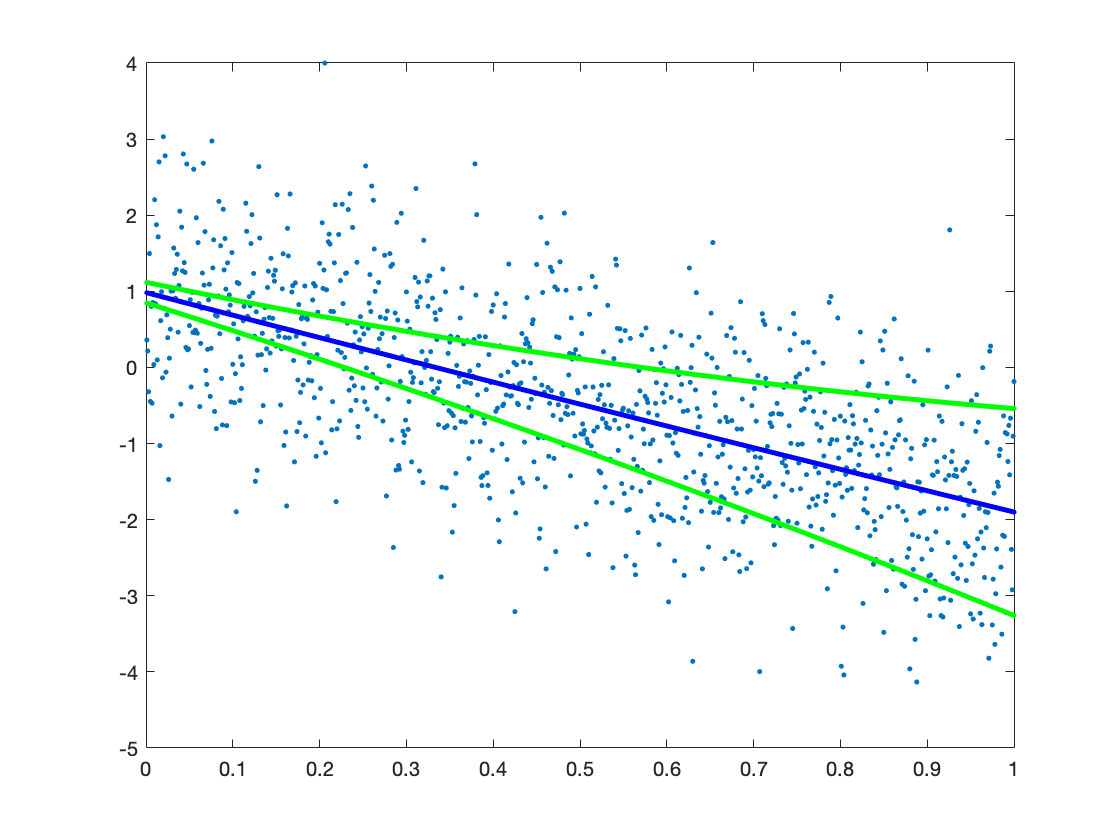


plot(x,y,'.', x,yh, '.r', x,yh1, '.g',  x,yh2, '.g', x,yh3, '.b' )


R2=[ones(length(x),1), x]

R2 =     1.0000    0.0010
    1.0000    0.0020
    1.0000    0.0030
    1.0000    0.0040
    1.0000    0.0050
    1.0000    0.0060
    1.0000    0.0070
    1.0000    0.0080
    1.0000    0.0090
    1.0000    0.0100



B2=inv((R2.')*R2)*((R2.')*y)

B2 =     0.9677
   -2.8835



yh22=R2*B2

yh22 =     0.9648
    0.9620
    0.9591
    0.9562
    0.9533
    0.9504
    0.9475
    0.9447
    0.9418
    0.9389


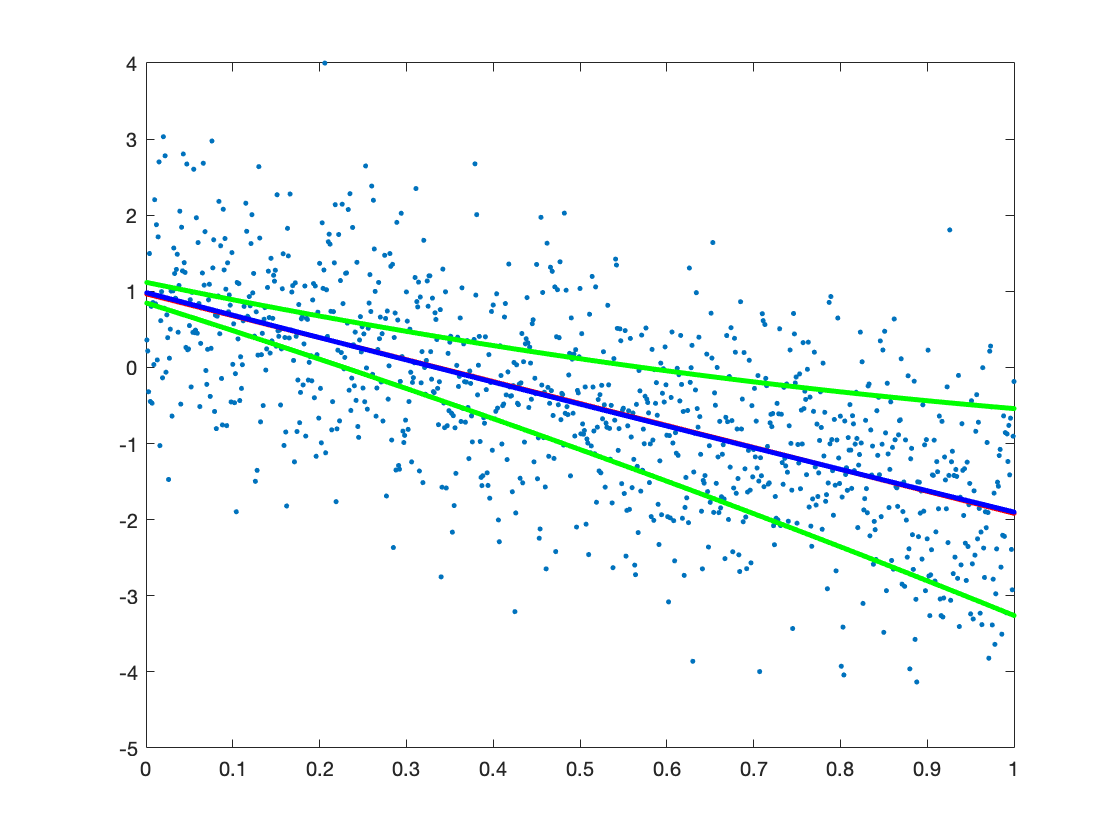


plot(x,y,'.', x,yh22, '.r', x,yh1, '.g',  x,yh2, '.g', x,yh3, '.b' )


%new model

cov2=inv((R2.')*R2)

cov2 =     0.0040   -0.0060
   -0.0060    0.0120



sse2=(y-yh22).^2

sse2 =     0.3639
    0.5554
    1.6345
    0.2923
    1.9606
    0.0218
    2.0079
    0.0084
    0.8181
    1.6000



sse2=sum(sse2)

sse2 = 1.0039e+03


s2ls2=(2/997)*sse2

s2ls2 = 2.0137


covd2=diag(cov2)

covd2 =     0.0040
    0.0120



varB2=covd2*s2ls2

varB2 =     0.0081
    0.0242



conf_12= B2 + 1*sqrt(varB2)

conf_12 =     1.0575
   -2.7280


conf_22= B2 - 1*sqrt(varB2)

conf_22 =     0.8779
   -3.0389



yh12=R2*conf_12

yh12 =     1.0548
    1.0521
    1.0494
    1.0466
    1.0439
    1.0412
    1.0384
    1.0357
    1.0330
    1.0303


yh222=R2*conf_22

yh222 =     0.8749
    0.8718
    0.8688
    0.8657
    0.8627
    0.8597
    0.8566
    0.8536
    0.8506
    0.8475



yh3=R*((conf_1+conf_2)/2)

yh3 =     0.9809
    0.9780
    0.9750
    0.9720
    0.9690
    0.9660
    0.9631
    0.9601
    0.9571
    0.9541


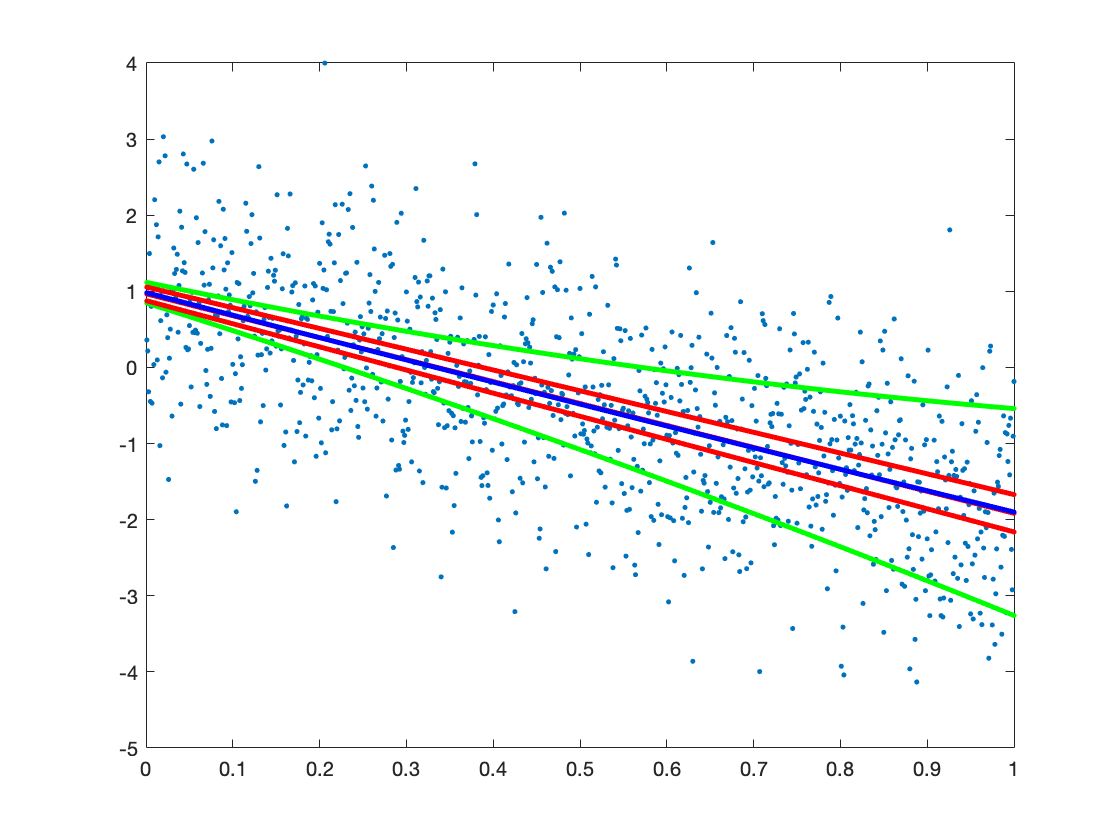


plot(x,y,'.', x,yh22, '.r', x,yh1, '.g',  x,yh2, '.g', x,yh3, '.b',x,yh12, '.r',x,yh222, '.r' )